% question 2. Record two utterances in your own voice: 
% the first utterance is three cardinal vowels a, i, u uttered 
% in sequence, the second utterance is “She had your dark 
% suit in greasy wash water all year” Obtain a spectrogram (use the 
% FFT function to obtain after splitting the speech signal 
% into frames) for both the utterances using Hamming window of 
% length 30 ms (narrow band spectrogram) and 5 ms (wideband spectrogram) 
% for window shift of 5 ms, and FFT length of 512.

% Short time analysis code
clear all
close all
clc

% recording audio 
fs = 16000;
NumSeconds = 5;
NumBits_quant = 16;
Num_channels = 1; % mono 1 channel, 2 for stereo


recorder = audiorecorder(fs, NumBits_quant, Num_channels);
disp('say a i u')

say a i u


recordblocking(recorder,NumSeconds);
disp('stop speaking')

stop speaking


Speech_data_vowels = getaudiodata(recorder);

Speech_data_vowels = Speech_data_vowels / max(abs(Speech_data_vowels));

% playing the audio on speaker
sound(Speech_data_vowels, fs)

% writing the audio to a file
audiowrite('abhishek_aiu.wav',Speech_data_vowels,fs);


recorder = audiorecorder(fs, NumBits_quant, Num_channels);
disp('say She had your dark suit in greasy wash water all year')

say She had your dark suit in greasy wash water all year


recordblocking(recorder,NumSeconds);
disp('stop speaking')

stop speaking


Speech_data_sentence = getaudiodata(recorder);

Speech_data_sentence = Speech_data_sentence / max(abs(Speech_data_sentence));

% playing the audio on speaker
sound(Speech_data_sentence, fs)

% writing the audio to a file
audiowrite('abhishek_second.wav',Speech_data_sentence,fs);

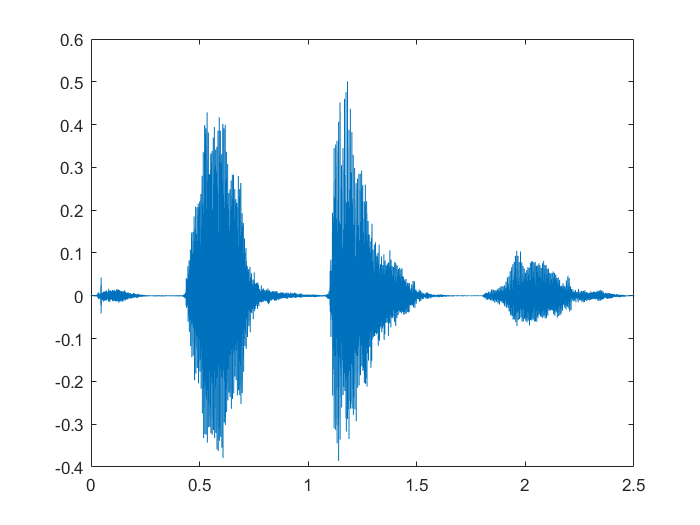


% read from the audio file
[speech_vowels, fs] = audioread('abhishek_aiu.wav');
speech_vowels = speech_vowels(floor(0.5*fs):floor(3*fs));
speech_vowels = speech_vowels(2:end) - 0.98*speech_vowels(1:end-1);
t= 0:(1/fs):(length(speech_vowels)-1)/fs;
figure;plot(t,speech_vowels)

sound(speech_vowels, fs)

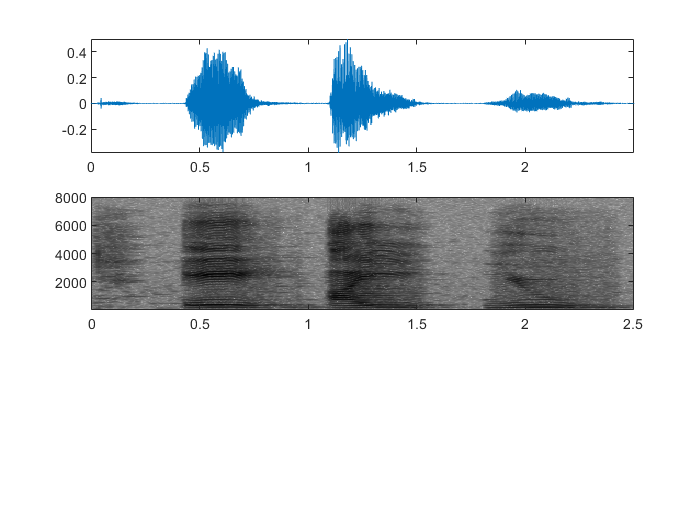


figure;
subplot(3,1,1)
plot(t, speech_vowels)
axis tight
subplot(3,1,2)
% obtain the spectrogram
wsize = round(30*0.001*fs);
o_lap = round(25*0.001*fs);
[b,f,t] = spec_calc(speech_vowels,512,fs,hamming(wsize),o_lap);

 
maxdbVal = max(max((abs(b)+eps)));
Initval = maxdbVal/(10000);

imagesc(t,f,20*log10((abs(b)+eps)/Initval));
set(gca,'YDir','normal');
colormap(gray(128));
% colorbar;
sgmap=1.0-colormap;
 
colormap(sgmap);

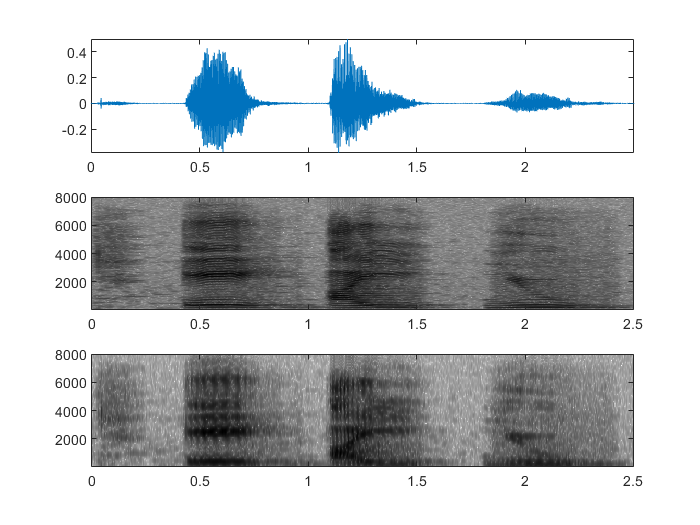


subplot(3,1,3)
% obtain the spectrogram
wsize = round(5*0.001*fs);
o_lap = round(0*0.001*fs);
[b,f,t] = spec_calc(speech_vowels,512,fs,hamming(wsize),o_lap);
 
maxdbVal = max(max((abs(b)+eps)));
Initval = maxdbVal/(10000);
 
imagesc(t,f,20*log10((abs(b)+eps)/Initval));
set(gca,'YDir','normal');
colormap(gray(128));
% colorbar;
sgmap=1.0-colormap;
 
colormap(sgmap);

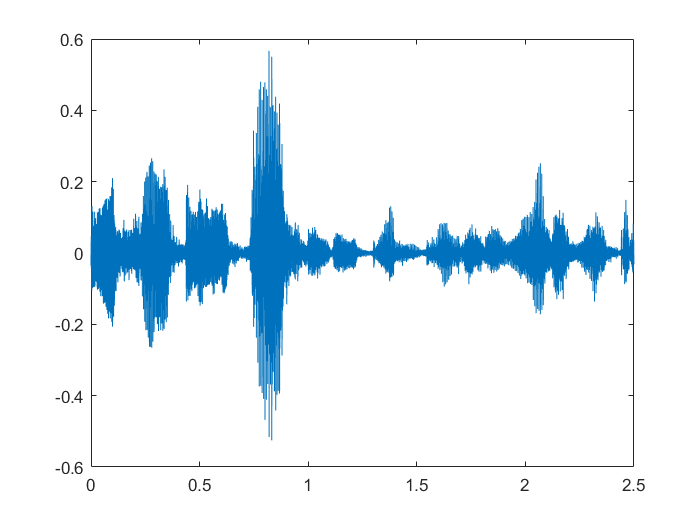

 
% for second utterance
% read from the audio file
[speech_second, fs] = audioread('abhishek_second.wav');
speech_second = speech_second(floor(0.5*fs):floor(3*fs));
speech_second = speech_second(2:end) - 0.98*speech_second(1:end-1);
t= 0:(1/fs):(length(speech_second)-1)/fs;
figure;plot(t,speech_second)

sound(speech_second, fs)

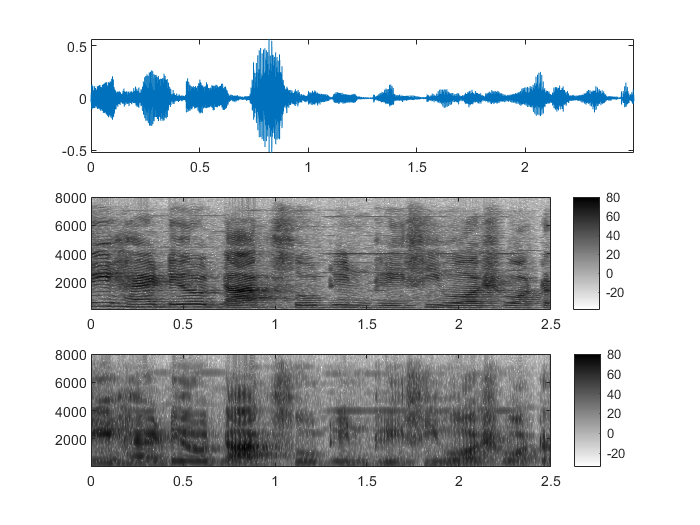


figure;
subplot(3,1,1)
plot(t, speech_second)
axis tight
subplot(3,1,2)
% obtain the spectrogram
wsize = round(30*0.001*fs);
o_lap = round(25*0.001*fs);
[b,f,t] = spec_calc(speech_second,512,fs,hamming(wsize),o_lap);
 
 
maxdbVal = max(max((abs(b)+eps)));
Initval = maxdbVal/(10000);

imagesc(t,f,20*log10((abs(b)+eps)/Initval));
set(gca,'YDir','normal');
colormap(gray(128));
colorbar;
sgmap=1.0-colormap;
 
colormap(sgmap);

subplot(3,1,3)
% obtain the spectrogram
wsize = round(5*0.001*fs);
o_lap = round(0*0.001*fs);
[b,f,t] = spec_calc(speech_second,512,fs,hamming(wsize),o_lap);
 
maxdbVal = max(max((abs(b)+eps)));
Initval = maxdbVal/(10000);
 
imagesc(t,f,20*log10((abs(b)+eps)/Initval));
set(gca,'YDir','normal');
colormap(gray(128));
colorbar;
sgmap=1.0-colormap;
 
colormap(sgmap);

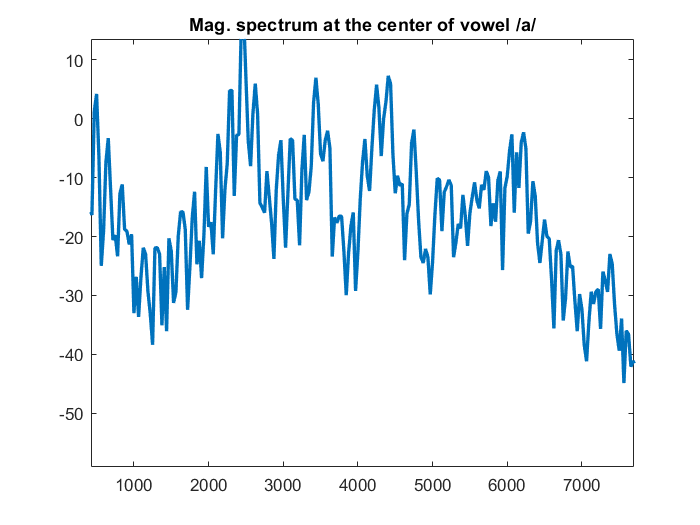

 
a_midpoint = 0.4813; % in sec obtained from the plot
i_midpoint = 1.179;
u_midpoint = 1.915;
 
a_midpoint_sample = round(a_midpoint*fs);
i_midpoint_sample = round(i_midpoint*fs);
u_midpoint_sample = round(u_midpoint*fs);
 
half_wideband_windwolen = round(30*0.001*fs/2);
sig = speech_vowels(a_midpoint_sample-half_wideband_windwolen:a_midpoint_sample+half_wideband_windwolen);
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
figure; plot (freq, 20*log10( abs(spec(1:257))),'LineWidth',2);
title('Mag. spectrum at the center of vowel /a/')

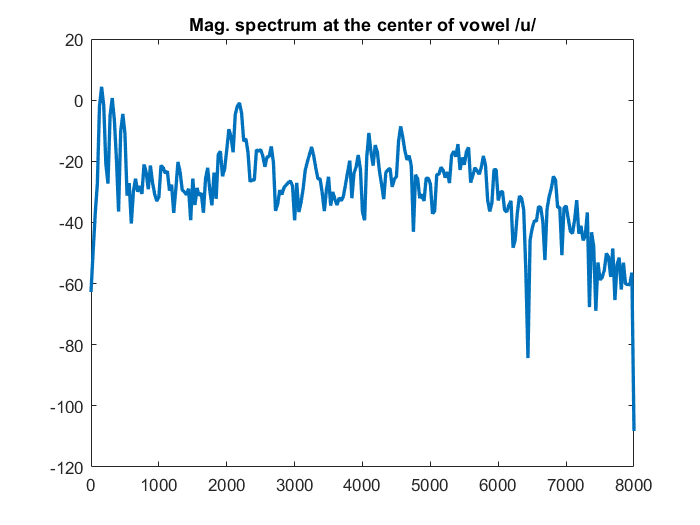

 
sig = speech_vowels(u_midpoint_sample-half_wideband_windwolen:u_midpoint_sample+half_wideband_windwolen);
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
figure; plot (freq, 20*log10( abs(spec(1:257))),'LineWidth',2);
title('Mag. spectrum at the center of vowel /u/')

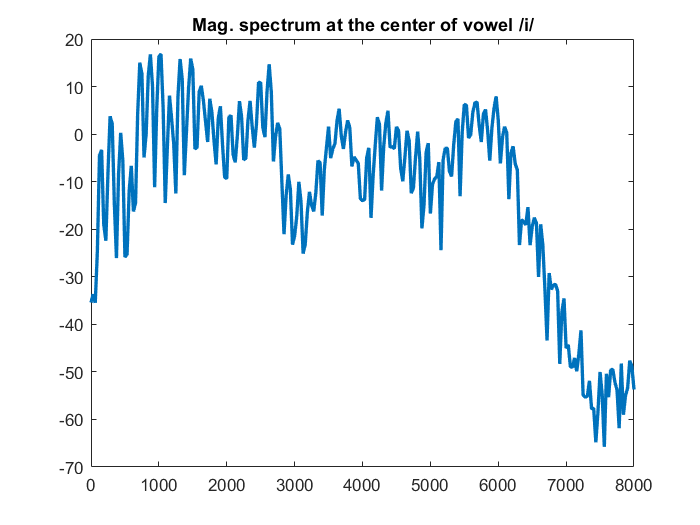

 
 
sig = speech_vowels(i_midpoint_sample-half_wideband_windwolen:i_midpoint_sample+half_wideband_windwolen);
spec = fft(sig.*hamming(length(sig)), 512);
freq = (0:256)*(fs/512);
figure; plot (freq, 20*log10( abs(spec(1:257))),'LineWidth',2);
title('Mag. spectrum at the center of vowel /i/')